## Extraction of the Lookup Table

% Extraction of the Lookup Table for Two Cell Populations
% Configuration
root = '/Users/hp024/Documents/maelyne/MRI/Diffusion/monte-carlo-simulation-sphere-PGSE-main/data';  
projname = 'AMBER_maelyne';
population_type = 'lognorm';
population_label = [population_type, '_population_RealisticTests2_V3'];
projectpath = fullfile(root, projname, population_label);

lut_file = fullfile(projectpath, 'lookup_table_two_pop.mat');

% If the look up table already exists in the directory
if isfile(lut_file)
    fprintf('Loading existing lookup table for two populations...\n');
    load(lut_file, 'params', 'signals_4D', 'sequence');
else
    fprintf('Lookup table not found. Running generation for two populations...\n');
    params_file = fullfile(projectpath, 'params_in.txt');

    if exist(params_file, 'file')
        params_data = readmatrix(params_file);
        Ncombos = size(params_data, 1);
    else
        error('params_in.txt not found in %s', projectpath);
    end

    simdir = fullfile(projectpath, 'sphere_0001'); %if we assume that the b-values and the directions of the gradients are the same for every file sphere_####

    % Load bvecs from gradient_btab.txt
    btab_raw = readmatrix(fullfile(simdir, 'gradient_bvalstab.txt'));
    [C, IA, IC] = unique(btab_raw);
    bval = C/1000;
    n_bvec = IA(2)-IA(1);
    Btab = readmatrix(fullfile(simdir, 'gradient_btab.txt'));
    btab = reshape(Btab, 4, []); %gradient_btab is a vector of size n_bval*n_bvec*4 
    bvecs = btab(2:end,1:n_bvec).';  
    
    % Load diffusion times and pulse widths
    TD = readmatrix(fullfile(simdir, 'TD_array.txt')); 
    pulse_widths = readmatrix(fullfile(simdir, 'gradient_DELdel.txt'));
    pulse_widths = reshape(pulse_widths, 2, []).';
    delta = pulse_widths(:,2);
    
    % Compute derived values  
    n_bval = numel(bval);
    n_del = numel(TD);
    n_signals = n_bvec * n_bval * n_del;
    
    % Initialize sequence struct
    sequence.bval = bval;
    sequence.bvecs = bvecs;
    sequence.n_bval = n_bval;
    sequence.n_bvec = n_bvec;
    sequence.n_del = n_del;
    sequence.TD = TD;
    sequence.delta = delta(1:n_del);  % just in case length mismatch
    
    % Extraction for 2 populations
    params = zeros(Ncombos, 7);     % f, Dex, rmean, rsd, kappa_alive, kappa_dead, f_alive
    signals_4D = zeros(Ncombos, n_del, n_bval, n_bvec);  % [i × d × b × v]
    
    % Population evolution over time
    % population_evolution = struct();
    % population_evolution.NParICS_alive = zeros(Ncombos, n_del);
    % population_evolution.NParICS_dead = zeros(Ncombos, n_del);
    % population_evolution.NParICS_total = zeros(Ncombos, n_del);
    
    % Loop over simulations
    for i = 1:Ncombos
        simname = sprintf('sphere_%04d', i);
        simdir = fullfile(projectpath, simname);
        
        % --- Load input parameters ---
        % Parameters are now saved with 10 values in sim_para.txt:
        % dt, TN, NPar, Din, Dex, kappa_alive, kappa_dead, f_alive, initFlag, res
        parafile = fullfile(simdir, 'sim_para.txt');
        if ~exist(parafile, 'file')
            warning('Missing sim_para.txt for simulation %d', i);
            continue;
        end
        paravalues = readmatrix(parafile);
        
        % Extract parameters (adjusted indices for new format)
        Din = paravalues(4); 
        Dex = paravalues(5);
        kappa_alive = paravalues(6);
        kappa_dead = paravalues(7);
        f_alive = paravalues(8);
        
        % --- Load geometric parameters ---
        pop_para_file = fullfile(simdir, 'population_para.txt');
        if exist(pop_para_file, 'file')
            pop_para = readmatrix(pop_para_file);
            rmean = pop_para(1);
            rsd = pop_para(2);
            f = pop_para(4);
        else
            % Fallback: calculate from geometry files
            rCir = readmatrix(fullfile(simdir, 'phantom_rCir.txt'));
            rmean = mean(rCir);
            rsd = std(rCir);
            f = sum(4/3*pi*rCir.^3); % volume fraction
        end
        
        % --- Store main parameters (extended) ---
        params(i,:) = [f, Dex, rmean, rsd, kappa_alive, kappa_dead, f_alive];
        
        % --- Load signals ---
        sigfile = fullfile(simdir, 'sig_diffusion.txt');
        sig = readmatrix(sigfile);  % should be [n_signals × 1]
    
        if numel(sig) ~= n_signals
            warning('Unexpected signal length for simulation %d', i);
            continue;
        end
        
        % in case the signal is negative
        sig(sig < 1e-6) = 1e-3;
        
        % reshape to [nDel × nBval × nBvec]
        sig3D = reshape(sig, [n_bvec, n_bval, n_del]); 
        sig3D = permute(sig3D, [3 2 1]);  % [d × b × v]
    
        % store in 4D array
        signals_4D(i,:,:,:) = sig3D; 
        
        % Progress indicator
        if mod(i, 100) == 0
            fprintf('Processed %d/%d simulations\n', i, Ncombos);
        end
    end
    
    % === SAVE EXTENDED LOOKUP TABLE ===
    save(fullfile(projectpath, 'lookup_table_two_pop.mat'), ...
        'params', 'signals_4D', 'sequence');
    
    fprintf('Extended lookup table for two populations saved successfully.\n');
    fprintf('Total simulations processed: %d\n', Ncombos);
end

Loading existing lookup table for two populations...


## Check the Lookup Table values

% === CHECK THE LOOKUP TABLE VALUES ===
fprintf('\n=== VERIFICATION ===\n');


=== VERIFICATION ===



bval = sequence.bval;
TD = sequence.TD;
bvecs = sequence.bvecs;

% Original displays for verification
disp('--- b values ---');

--- b values ---


disp(bval);

         0
    0.2500
    0.5000
    0.7000
    0.8000
    1.0000
    1.2000
    1.6000
    2.0000
    3.5000



disp('--- Diffusion times ---');

--- Diffusion times ---


disp(TD);

    15
    45
    75



disp('--- Gradient directions ---');

--- Gradient directions ---


disp(bvecs);

    0.7071         0    0.7071
   -0.7071         0    0.7071
         0    0.7071    0.7071
         0    0.7071   -0.7071
    0.7071    0.7071         0
   -0.7071    0.7071         0




% === NEW: POPULATION VERIFICATION ===
fprintf('\n=== POPULATION PARAMETERS (first 5 simulations) ===\n');


=== POPULATION PARAMETERS (first 5 simulations) ===


fprintf('Sim\tf_alive\tkappa_alive\tkappa_dead\n');

Sim	f_alive	kappa_alive	kappa_dead


for i = 1:min(5, size(params, 1))
    fprintf('%d\t%.3f\t\t%.4f\t\t%.4f\n', ...
            i, params(i,7), ...
            params(i,5), ...
            params(i,6));
end

1	0.041		0.0300		0.1418
2	0.041		0.0300		0.1418
3	0.041		0.0300		0.1418
4	0.041		0.0300		0.1418
5	0.041		0.0300		0.1418




% === SIGNAL VERIFICATION ===
i = 1;
s = squeeze(signals_4D(i,:,:,:));  % [nDel × nBval × nBvec]

fprintf('\n=== SIGNAL VERIFICATION (simulation 1) ===\n');


=== SIGNAL VERIFICATION (simulation 1) ===


fprintf('Signal shape: [%d × %d × %d]\n', size(s, 1), size(s, 2), size(s, 3));

Signal shape: [3 × 10 × 6]


fprintf('b=0 signals (should be ~1): ');

b=0 signals (should be ~1): 

fprintf('%.3f ', s(1, 1, :)); % First diffusion time, b=0, all directions

100000.000 100000.000 100000.000 100000.000 100000.000 100000.000 

fprintf('\n');


fprintf('\n=== LUT GENERATION COMPLETE ===\n');


=== LUT GENERATION COMPLETE ===


## Plot average signal vs cell density and Dex

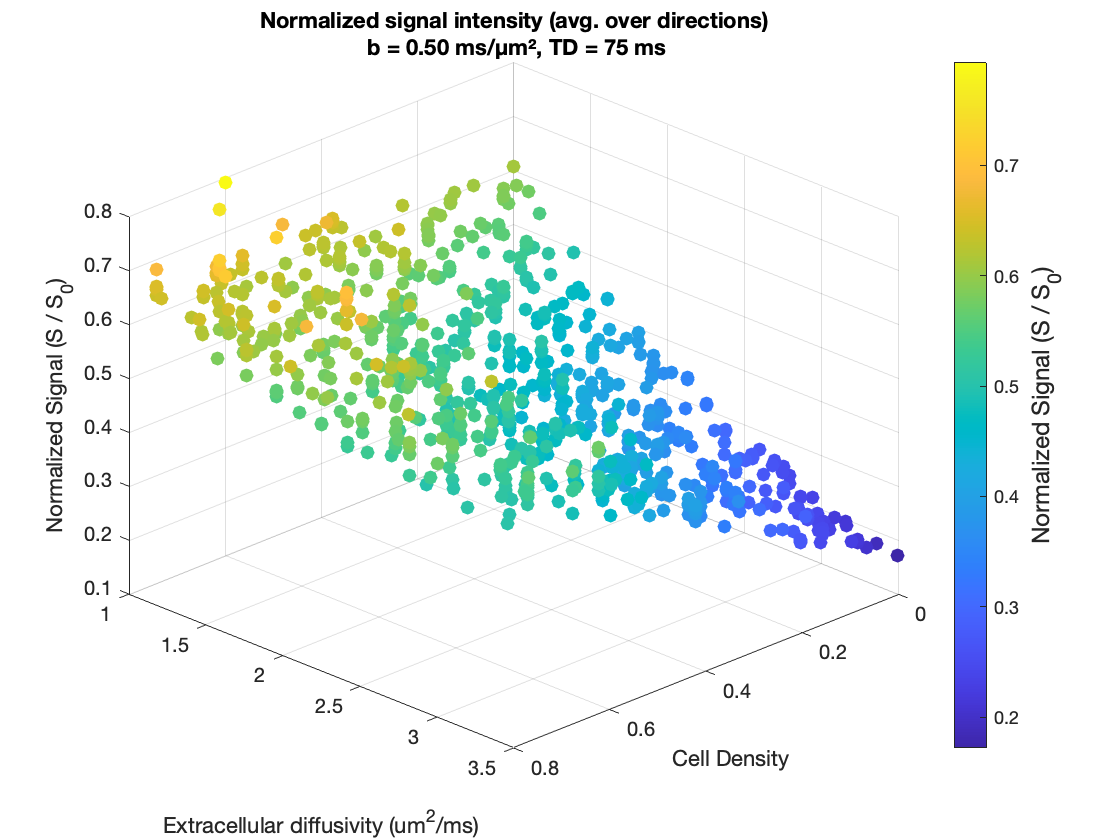

% Indexes of bvalue and diffusion time
b0_index = 1;
b_index = 3;
td_index = 3;

% Parameters extraction
f_all     = params(:,1);
Dex_all   = params(:,2);
rmean_all = params(:,3);
rsd_all   = params(:,4);
kappa_alive = params(:,5);
kappa_dead = params(:,6);
f_alive_all = params(:,7);

% Filter : RSD < 2
valid_idx = rsd_all < 10 & f_alive_all < 1; % & rmean_all>28 & rmean_all<32

f_all     = f_all(valid_idx);
Dex_all   = Dex_all(valid_idx);
sig_temp  = squeeze(signals_4D(valid_idx, td_index, b_index, :));  % [N × n_bvecs]
S0_temp   = squeeze(signals_4D(valid_idx, td_index, b0_index, :)); %for normalization

% Average over directions
sig_avg = mean(sig_temp, 2);  % [N × 1]
S0_avg  = mean(S0_temp, 2);

% Normalize
sig_norm = sig_avg ./ S0_avg;

% Scatter plot
figure;
scatter3(f_all, Dex_all, sig_norm, 50, sig_norm, 'filled');
xlabel('Cell Density');
ylabel('Extracellular diffusivity (um^2/ms)');
zlabel('Normalized Signal (S / S_0)');
b_value_real = bval(b_index);
TD_real = TD(td_index);
title(sprintf('Normalized signal intensity (avg. over directions)\n b = %.2f ms/µm², TD = %d ms', b_value_real, TD_real));


% Caption
cb = colorbar;
cb.Label.String = 'Normalized Signal (S / S_0)';
cb.Label.FontSize = 12;

view(135, 30);
grid on;

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/Nec_scatter3_b%d_TD%d.png', b_value_real*100, TD_real); 
saveas(gcf, filename);

## Plot percentage of alive cells repartition

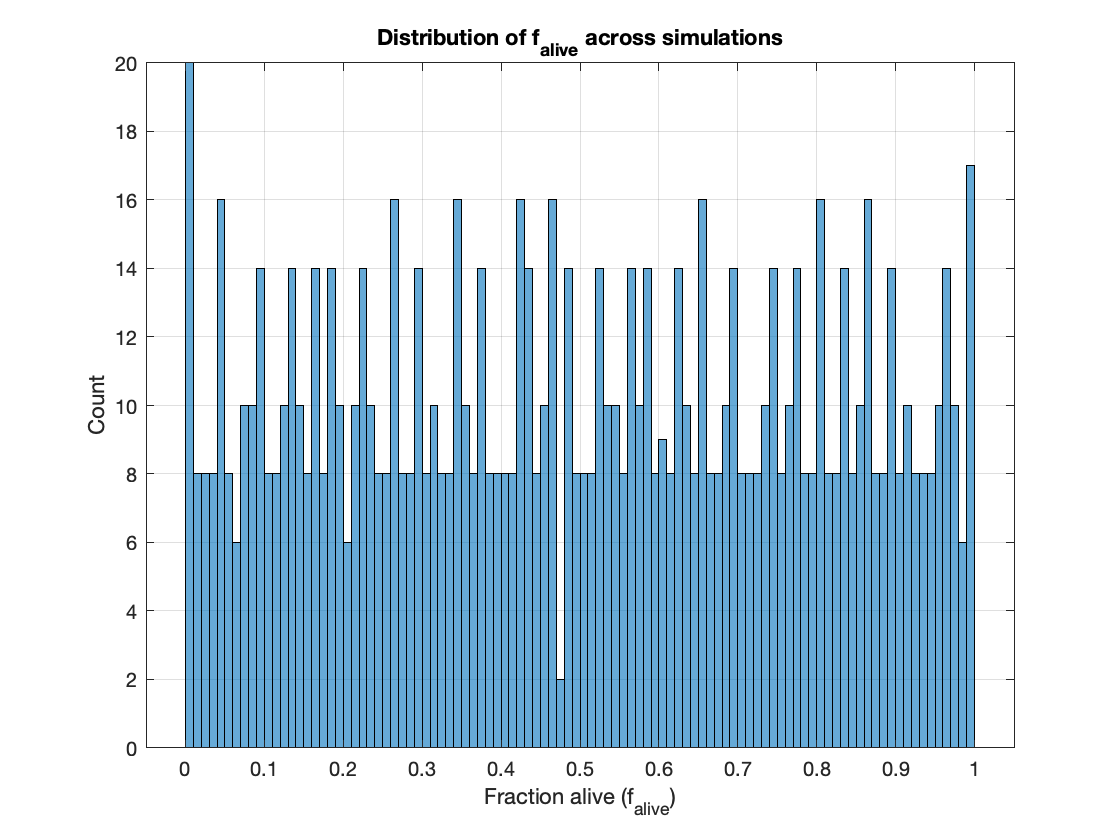

% Extraction
f_alive_all = params(:,7);

% Filter
rsd_all = params(:,4);
valid_idx = rsd_all < 10;
f_alive_valid = f_alive_all(valid_idx);

% Histogram
figure;
histogram(f_alive_valid, 100); 
xlabel('Fraction alive (f_{alive})');
ylabel('Count');
title('Distribution of f_{alive} across simulations');
grid on;

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/Nec_distribution_f_alive'); 
saveas(gcf, filename);

## Plot signal intensity vs bvalue and diffusion time

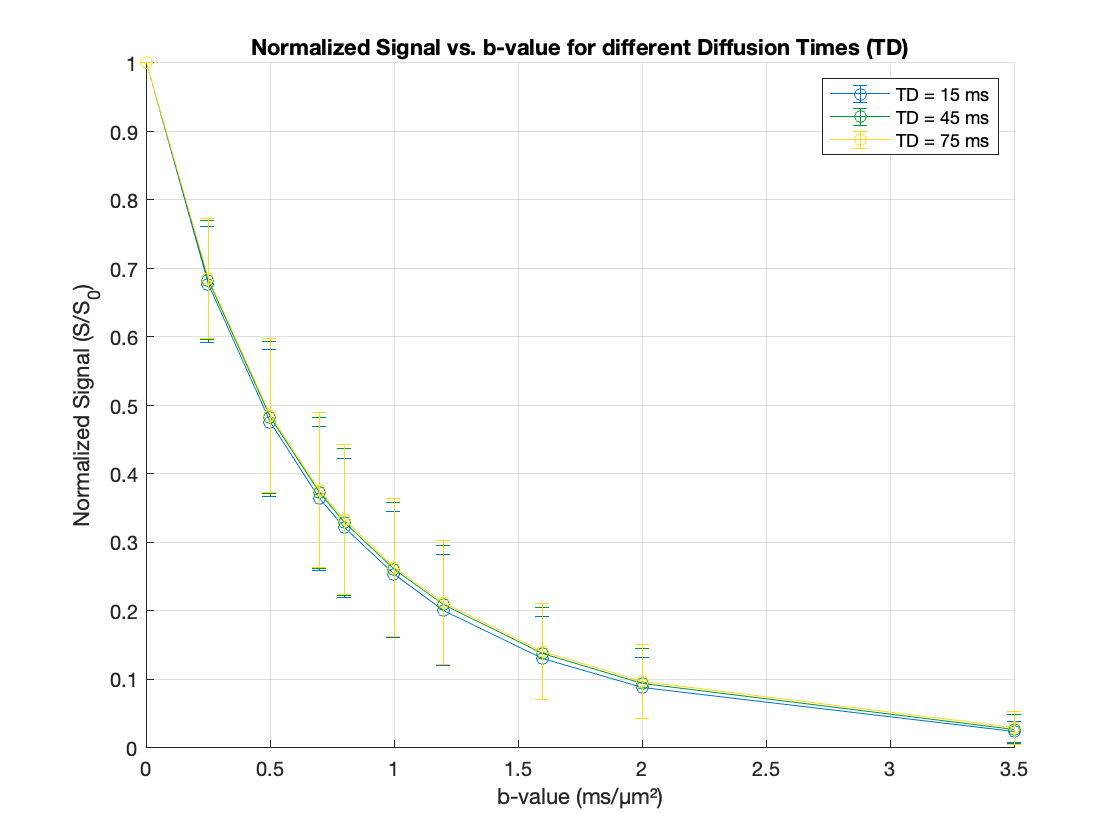

% Extract bvalue and diffusion time 
bvals = sequence.bval;     % [n_bval × 1]
TDs   = sequence.TD;       % [n_del × 1]

% Filter simulations (<10 means all rsd)
valid_idx = rsd_all < 10;
signals_valid = signals_4D(valid_idx, :, :, :);  % [N × n_del × n_bval × n_bvec]

% Average over directions
signals_avg_bvec = squeeze(mean(signals_valid, 4));  % [N × n_del × n_bval]

% Average over N combinations
signals_mean = squeeze(mean(signals_avg_bvec, 1));  % [n_del × n_bval]
signals_std  = squeeze(std(signals_avg_bvec, 0, 1)); % [n_del × n_bval]

% --- Normalization by b=0 (assume first bval is 0) ---
S0 = signals_mean(:, 1);   % [n_del × 1] baseline (b=0)
signals_mean_norm = signals_mean ./ S0;   % broadcasting over columns
signals_std_norm  = signals_std ./ S0;    % same normalization for std

% Plot
figure; hold on;
my_colors = [ ...
    0 0.45 0.8;   % blue
    0 0.6 0.2;    % green
    1.0 0.85 0.1  % yellow
];

for i = 1:numel(TDs)
    errorbar(bvals, signals_mean_norm(i,:), signals_std_norm(i,:), ...
        '-o', 'Color', my_colors(i,:), 'DisplayName', sprintf('TD = %.0f ms', TDs(i)));
end

xlabel('b-value (ms/µm²)');
ylabel('Normalized Signal (S/S_0)');
title('Normalized Signal vs. b-value for different Diffusion Times (TD)');
legend('Location', 'northeast');
grid on;

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/Nec_sig_exp_decay.png'); 
saveas(gcf, filename);

## Plot signal intensity vs cell density and Dex colored accroding to the fraction of alive cells

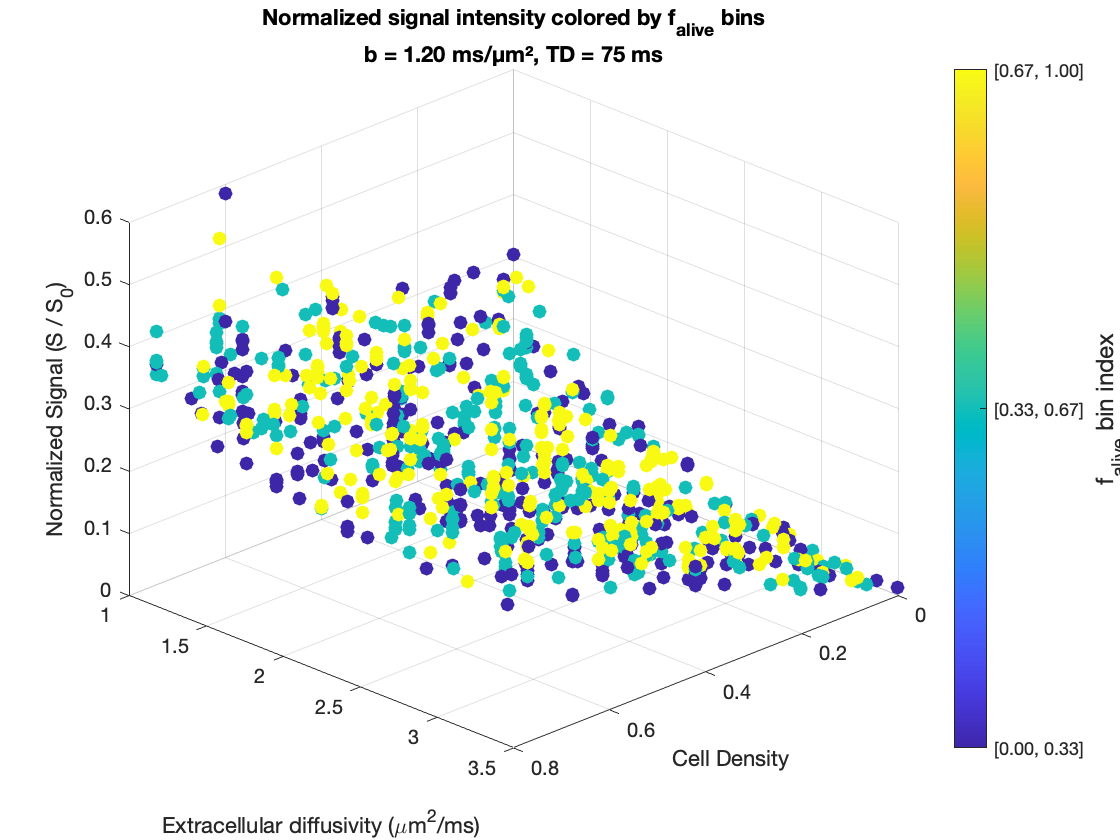

% Indexes of bvalue and diffusion time
b0_index = 1;
b_index = 7;
td_index = 3;

% Parameters extraction
f_all       = params(:,1);
Dex_all     = params(:,2);
rmean_all   = params(:,3);
rsd_all     = params(:,4);
kappa_alive = params(:,5);
kappa_dead  = params(:,6);
f_alive_all = params(:,7);

% Filter : RSD < 10 & f_alive < 1
valid_idx = rsd_all < 10 & f_alive_all < 1; 

% Apply filter
f_all       = f_all(valid_idx);
Dex_all     = Dex_all(valid_idx);
f_alive_all = f_alive_all(valid_idx);
sig_temp    = squeeze(signals_4D(valid_idx, td_index, b_index, :));  % [N × n_bvecs]
S0_temp   = squeeze(signals_4D(valid_idx, td_index, b0_index, :)); %for normalization

% Average over directions
sig_avg = mean(sig_temp, 2);  % [N × 1]
S0_avg  = mean(S0_temp, 2);

% Normalize
sig_norm = sig_avg ./ S0_avg;

% --- Discretize f_alive into 3 bins ---
num_bins = 3;
edges = linspace(min(f_alive_all), max(f_alive_all), num_bins+1);
bin_ids = discretize(f_alive_all, edges); % Returns bin index for each point

% Scatter plot (colored by bin index)
figure;
scatter3(f_all, Dex_all, sig_norm, 50, bin_ids, 'filled');
xlabel('Cell Density');
ylabel('Extracellular diffusivity (\mum^2/ms)');
zlabel('Normalized Signal (S / S_0)');
b_value_real = bval(b_index);
TD_real = TD(td_index);
title(sprintf('Normalized signal intensity colored by f_{alive} bins\nb = %.2f ms/µm², TD = %d ms', b_value_real, TD_real));

% Colorbar
cb = colorbar;
cb.Label.String = 'f_{alive} bin index';
cb.Ticks = 1:num_bins;
cb.TickLabels = arrayfun(@(i) sprintf('[%.2f, %.2f]', edges(i), edges(i+1)), ...
                         1:num_bins, 'UniformOutput', false);
cb.Label.FontSize = 12;

view(135, 30);
grid on;

% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/Nec_scatter_bin_b%d_TD%d.png', b_value_real*100, TD_real);
saveas(gcf, filename);

## Plot signal intensity vs fraction of alive cells

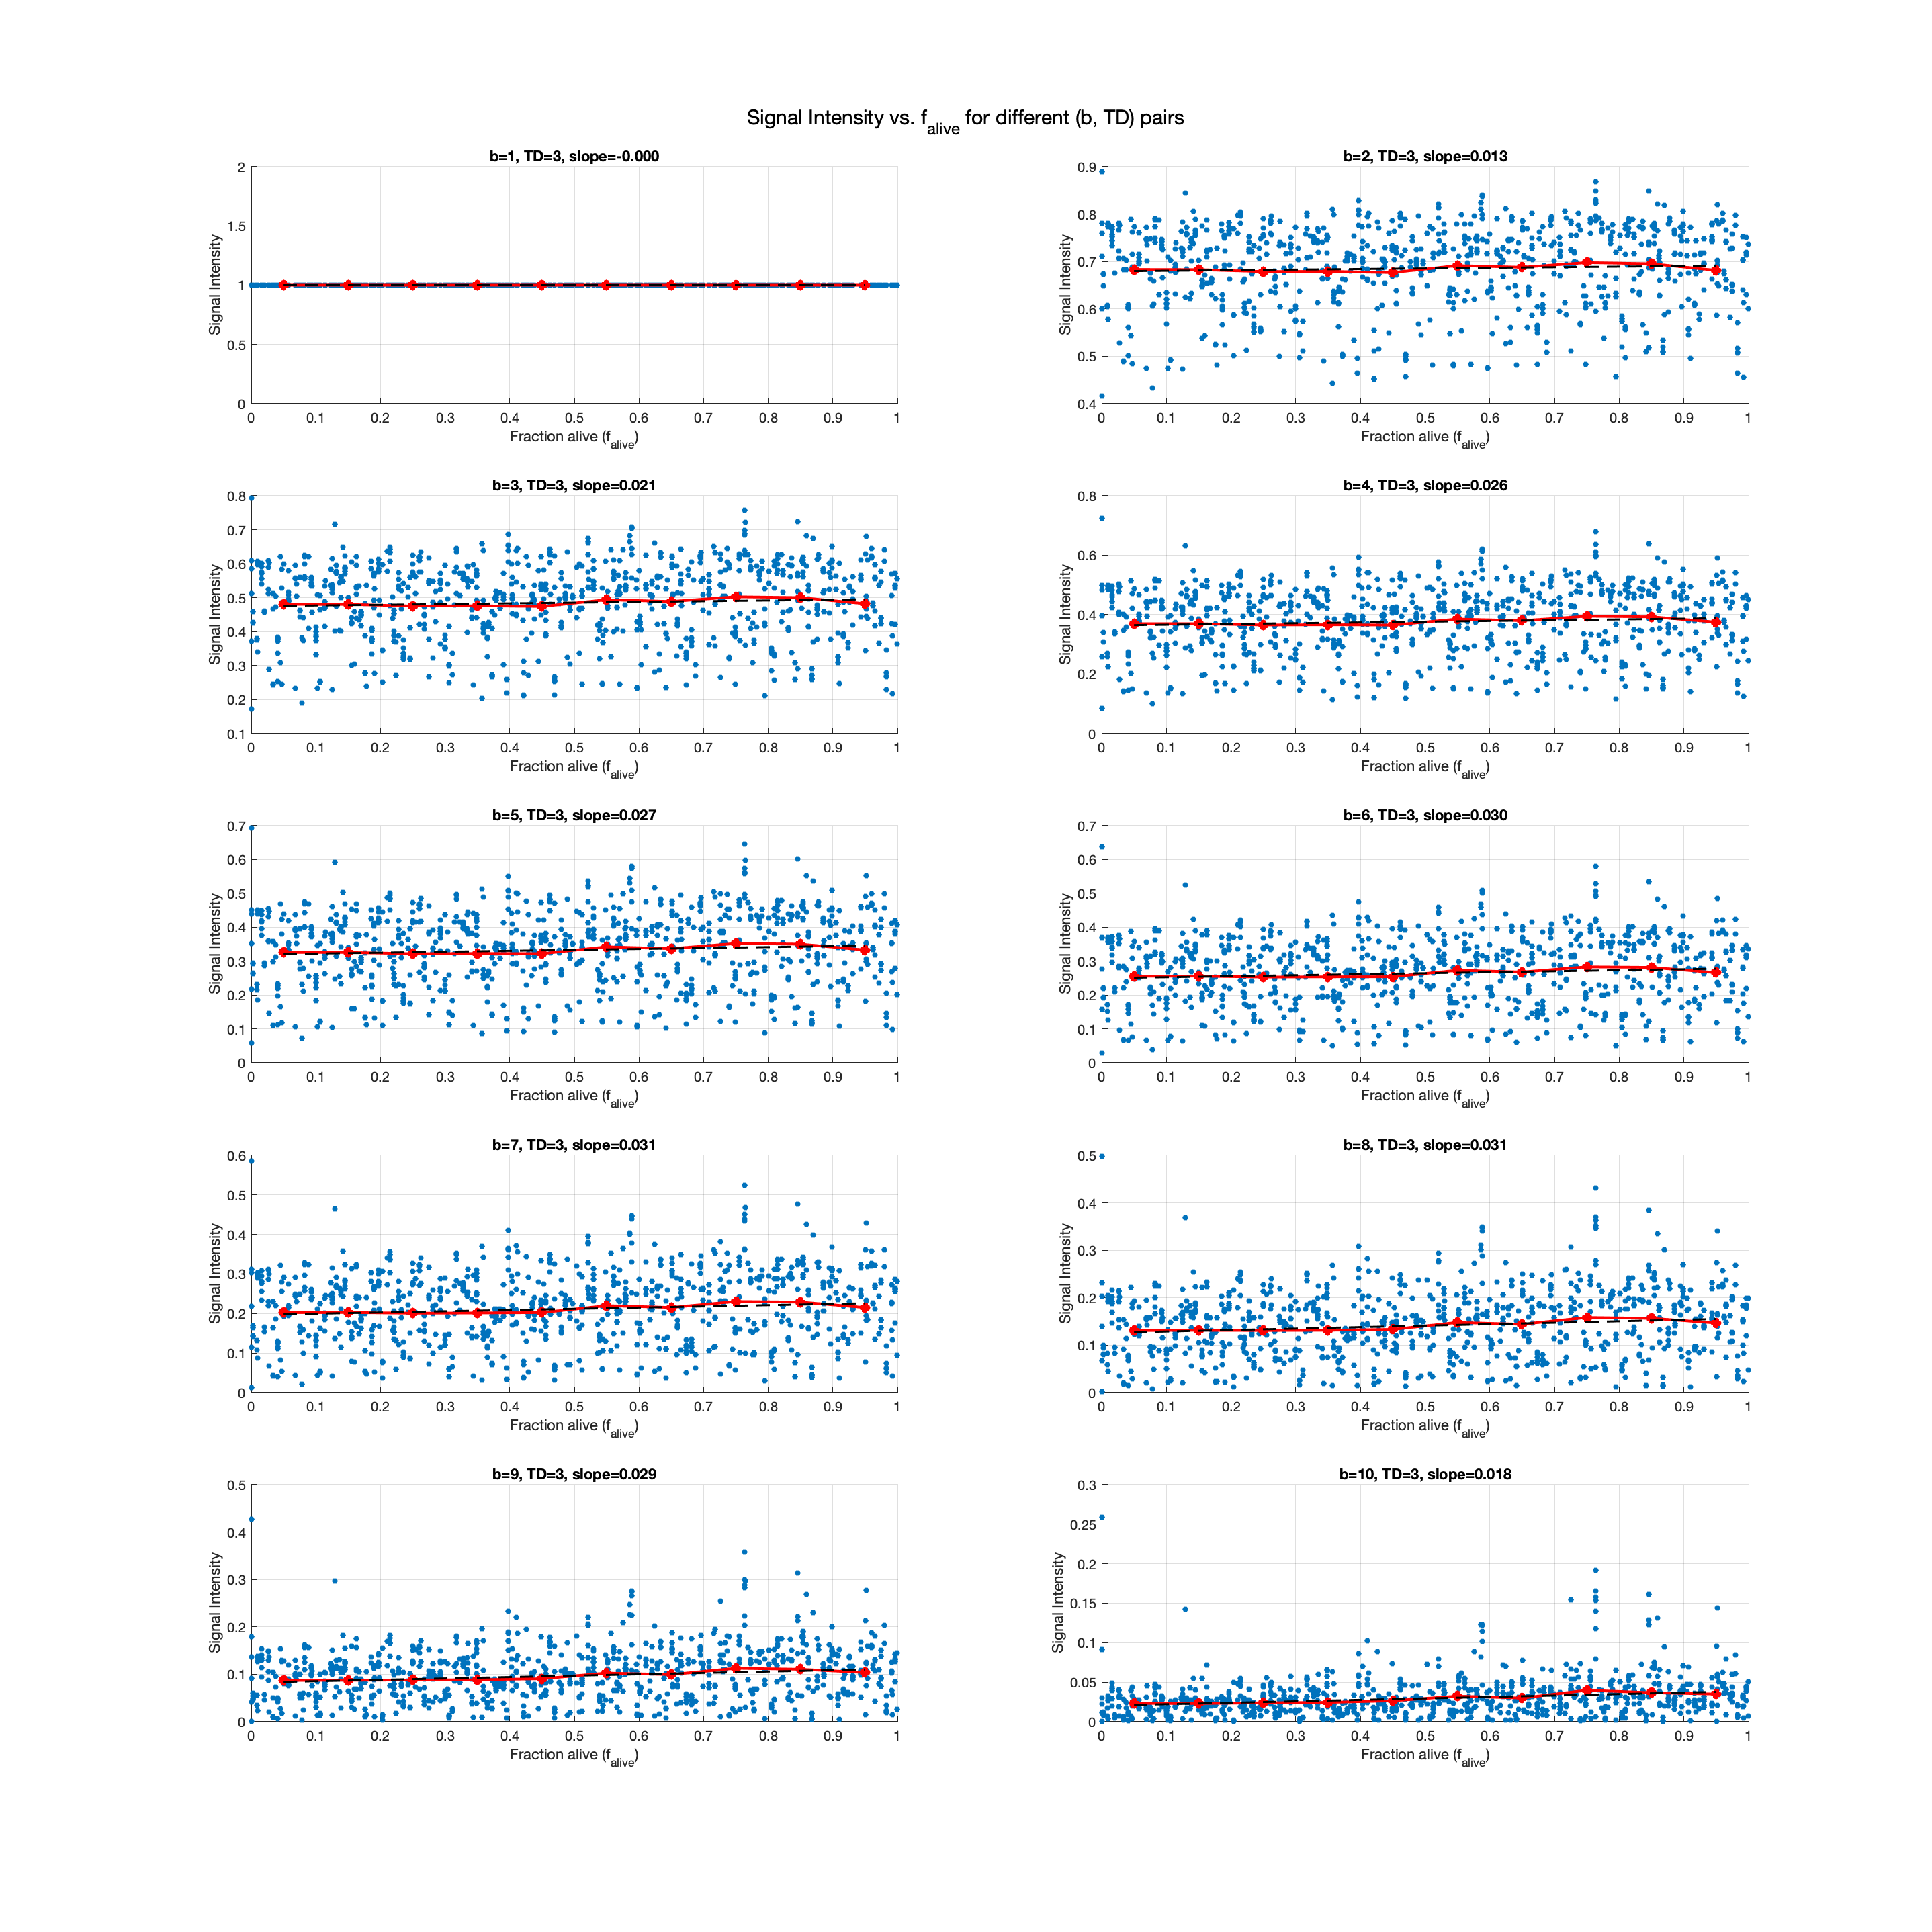

% Listes des valeurs à tester
b_values  = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10];
td_values = [3, 3, 3, 3, 3, 3, 3, 3, 3, 3];

num_bins = 10;

figure('Position', [100, 100, 1500, 1500]);

for k = 1:10
    b_index = b_values(k);
    td_index = td_values(k);
 
    % Extraction
    f_alive_all = params(:,7);
    rsd_all     = params(:,4);

    % Filtre
    valid_idx = rsd_all < 10 & f_alive_all < 1;
    f_alive_all = f_alive_all(valid_idx);

    % Signal extraction et moyenne directions
    sig_temp = squeeze(signals_4D(valid_idx, td_index, b_index, :));
    sig_avg  = mean(sig_temp, 2);
    S0_temp   = squeeze(signals_4D(valid_idx, td_index, b0_index, :)); %for normalization
    S0_avg  = mean(S0_temp, 2);
    sig_norm = sig_avg ./ S0_avg;
    
    % Binning
    edges = linspace(min(f_alive_all), max(f_alive_all), num_bins+1);
    bin_ids = discretize(f_alive_all, edges);
    bin_centers = 0.5*(edges(1:end-1) + edges(2:end));
    mean_sig = accumarray(bin_ids, sig_norm, [num_bins, 1], @mean, NaN);

    % --- Plot dans un subplot ---
    subplot(5, 2, k);
    scatter(f_alive_all, sig_norm, 20, 'filled');
    hold on;
    plot(bin_centers, mean_sig, '-o', 'Color', 'r', 'LineWidth', 2, 'MarkerFaceColor', 'r');

    % --- Régression linéaire sur la tendance ---
    coeffs = polyfit(bin_centers, mean_sig, 1); % 1 = régression linéaire
    slope = coeffs(1);  % coefficient directeur
    intercept = coeffs(2);

    % Tracer la droite de régression (optionnel)
    y_fit = polyval(coeffs, bin_centers);
    plot(bin_centers, y_fit, '--k', 'LineWidth', 1.5);

    % Afficher la pente dans le titre
    xlabel('Fraction alive (f_{alive})');
    ylabel('Signal Intensity');
    title(sprintf('b=%d, TD=%d, slope=%.3f', b_index, td_index, slope));

    grid on;
end

sgtitle('Signal Intensity vs. f_{alive} for different (b, TD) pairs');

## Plot signal intensity vs kappa_dead

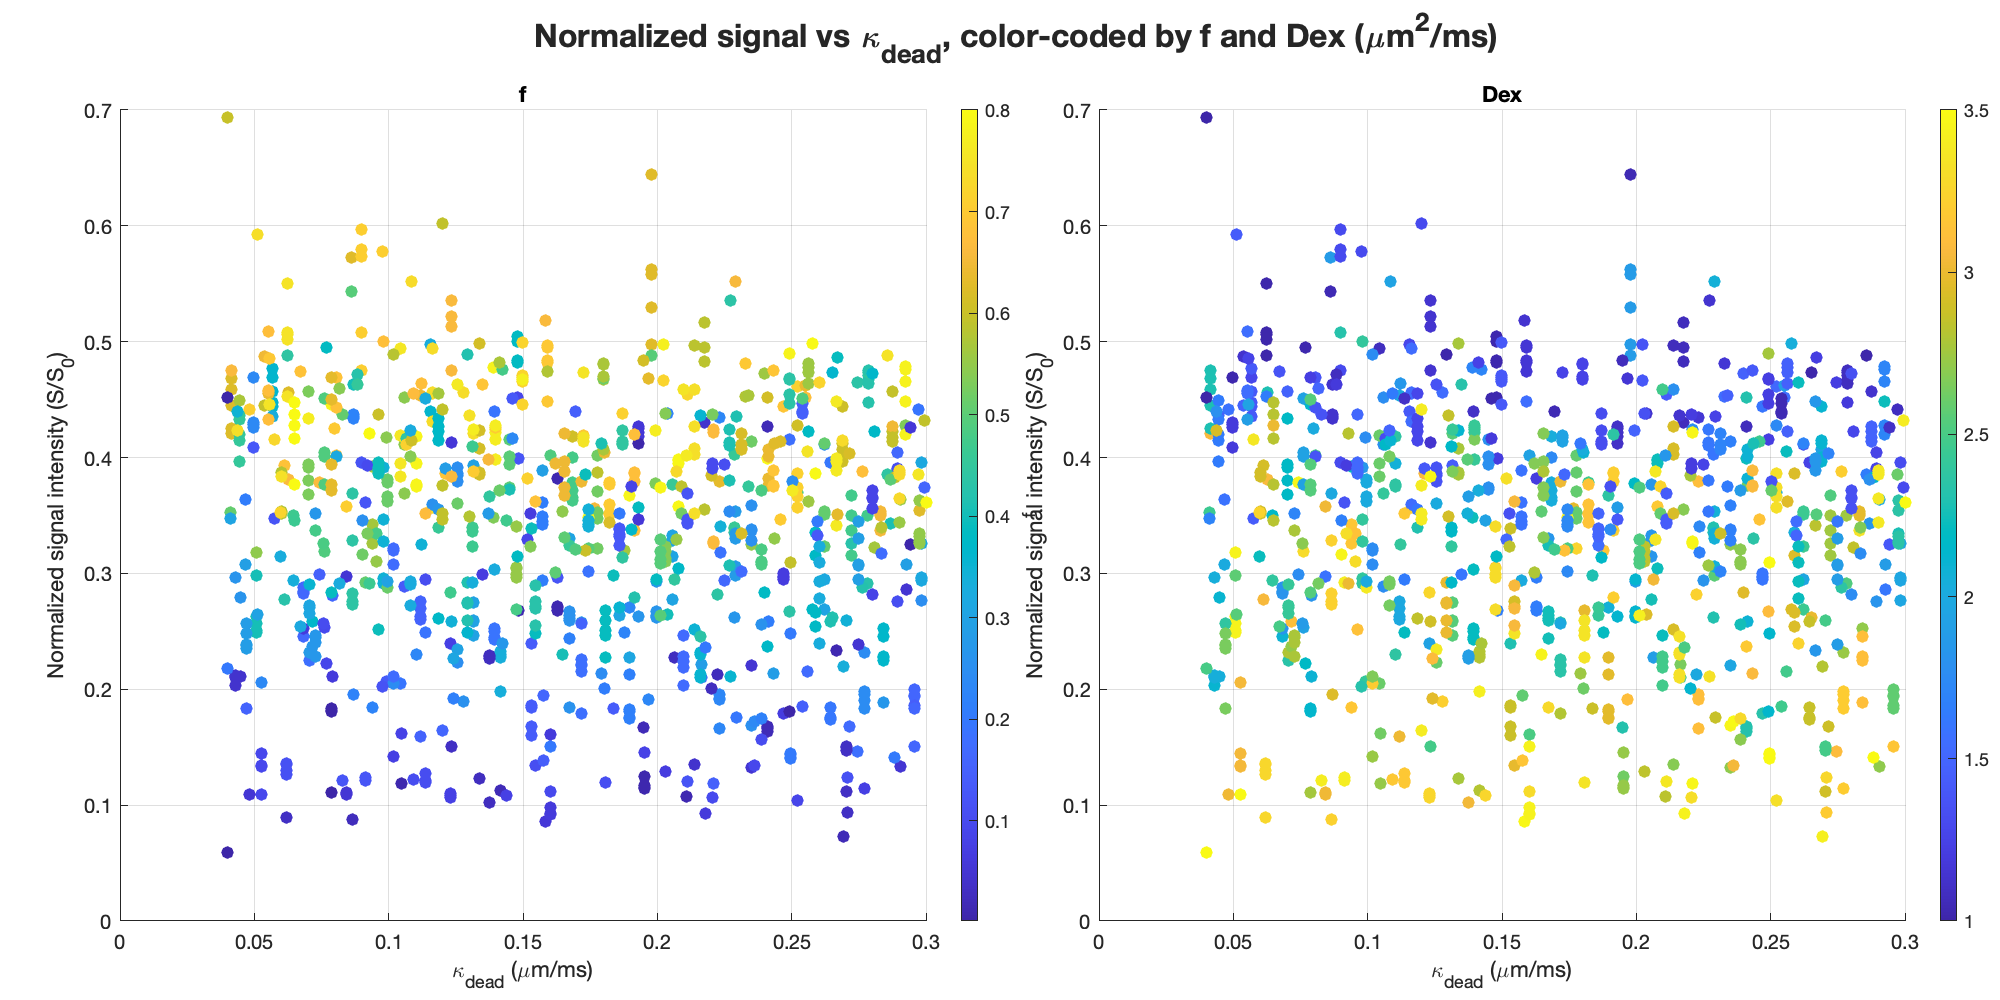

params_to_color = {'f', 'Dex'};  % noms pour légende
param_values = [params(:,1), params(:,2)];  % f et Dex
b0_index = 1;
b_index = 5;
td_index = 3;

% Filtre
valid_idx = params(:,4) < 10; % rsd < 10
kappa_dead_all = params(valid_idx,6);
sig_temp = squeeze(signals_4D(valid_idx, td_index, b_index, :));
sig_avg  = mean(sig_temp, 2);
S0_temp   = squeeze(signals_4D(valid_idx, td_index, b0_index, :)); %for normalization
S0_avg  = mean(S0_temp, 2);
sig_norm = sig_avg ./ S0_avg;

% Figure
figure('Position', [100, 100, 1000, 500]); % Ajustée pour 2 sous-figures
tiledlayout(1,2,'TileSpacing','compact','Padding','compact');

for i = 1:length(params_to_color)
    nexttile;
    values = param_values(valid_idx,i);
    scatter(kappa_dead_all, sig_norm, 40, values, 'filled');
    xlabel('\kappa_{dead} (\mum/ms)');
    ylabel('Normalized signal intensity (S/S_0)');
    title(params_to_color{i});
    grid on;
    cb = colorbar;
    cb.Label.String = params_to_color{i};
end
sgtitle('\bf Normalized signal vs \kappa_{dead}, color-coded by f and Dex (\mum^2/ms)', ...
        'FontSize', 16);


% Save figure in "Figures" folder
if ~exist('Figures', 'dir')
    mkdir('Figures');
end
filename = sprintf('Figures/Nec_scatter_bin_kappa.png');
saveas(gcf, filename);

## Plot signal vs kappa_dead and f_alive

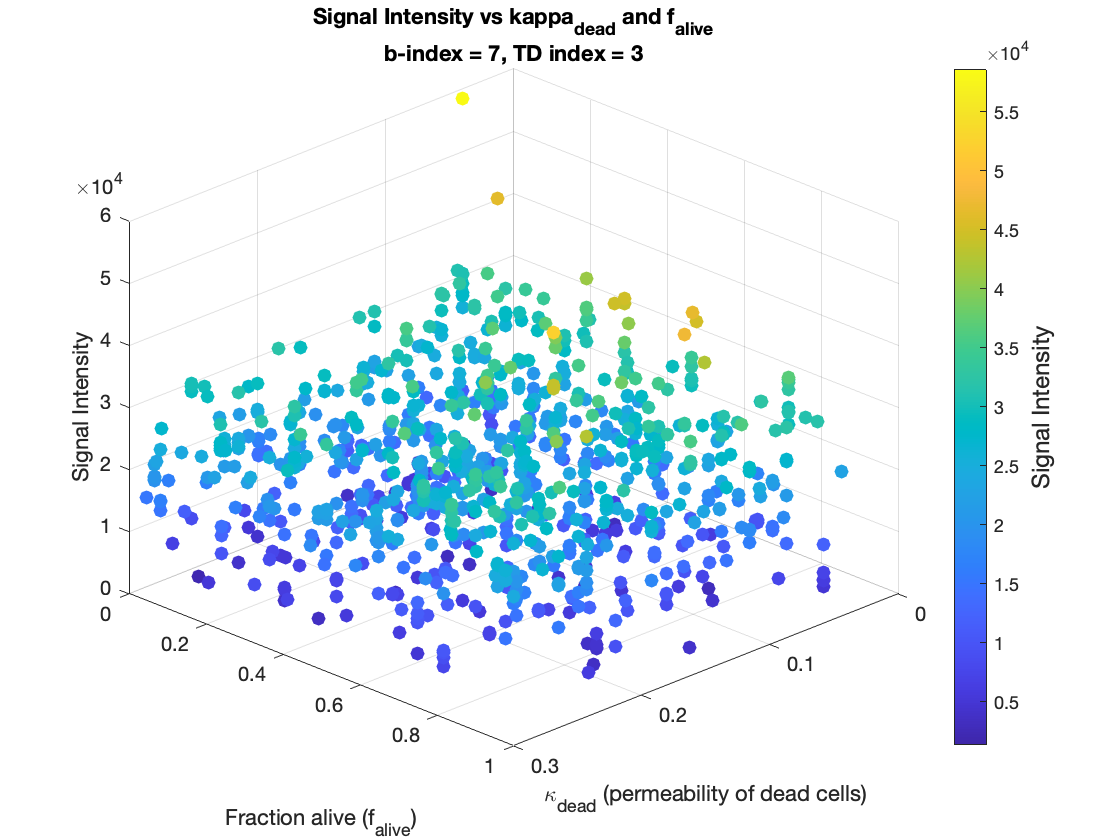

% Indexes of bvalue and diffusion time
b0_index = 1;
b_index = 7;
td_index = 3;

% Parameters extraction
f_alive_all = params(:,7);
kappa_dead_all = params(:,6);
rsd_all = params(:,4);

% Filter : RSD < 10 & f_alive < 1.2
valid_idx = rsd_all < 10 & f_alive_all < 1.2; 

% Apply filter
f_alive_all = f_alive_all(valid_idx);
kappa_dead_all = kappa_dead_all(valid_idx);
sig_temp = squeeze(signals_4D(valid_idx, td_index, b_index, :));  % [N × n_bvecs]

% Average over directions
sig_avg = mean(sig_temp, 2);  % [N × 1]

% Scatter 3D coloré par signal
figure;
scatter3(kappa_dead_all, f_alive_all, sig_avg, 50, sig_avg, 'filled');
xlabel('\kappa_{dead} (permeability of dead cells)');
ylabel('Fraction alive (f_{alive})');
zlabel('Signal Intensity');
title(sprintf('Signal Intensity vs kappa_{dead} and f_{alive}\nb-index = %d, TD index = %d', b_index, td_index));

% Colorbar
cb = colorbar;
cb.Label.String = 'Signal Intensity';
cb.Label.FontSize = 12;

view(135, 30);
grid on;

## Plot signal intensity vs kappa_dead and tendancies

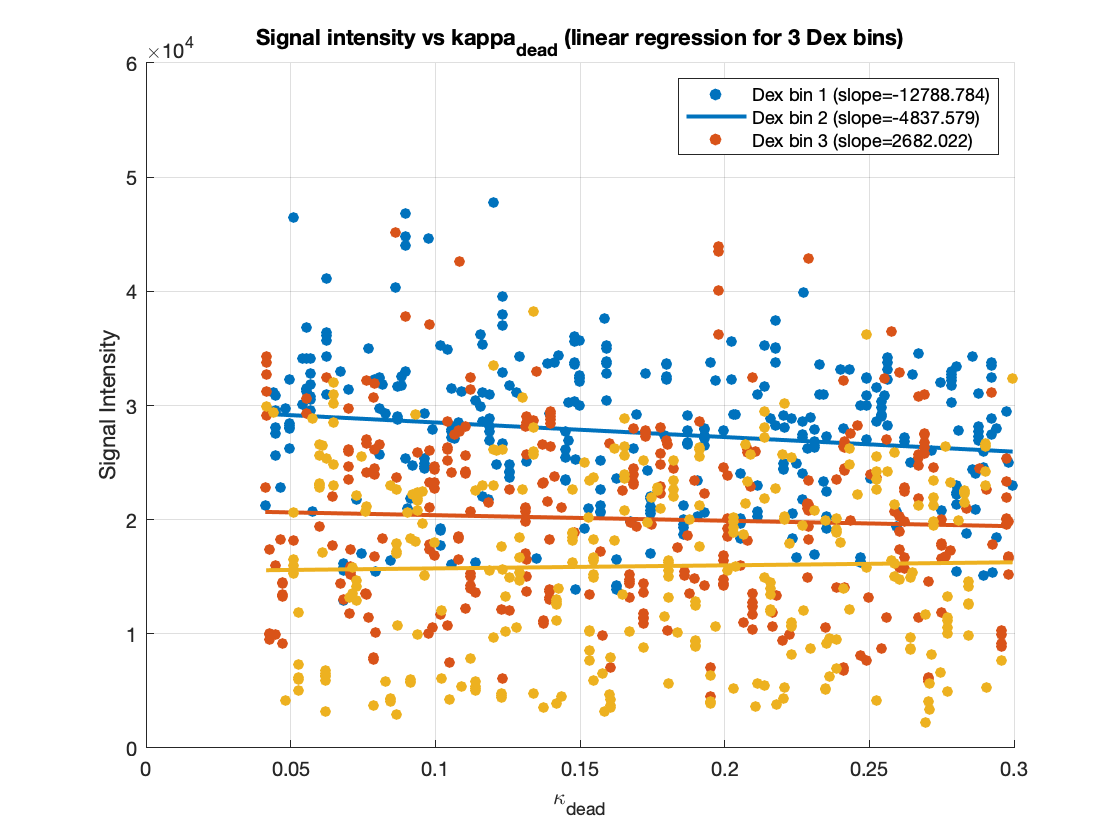

% Paramètres
b_index = 7;
td_index = 3;
num_bins = 3;  % nombre de bins pour Dex

% Extraction
Dex_all = params(:,2);
kappa_dead_all = params(:,6);
rsd_all = params(:,4);

% Filtre
valid_idx = rsd_all < 10; 
max_points = 1024;
valid_idx = find(valid_idx);          % convertir en indices
if length(valid_idx) > max_points
    valid_idx = valid_idx(1:max_points);
end
kappa_dead = kappa_dead_all(valid_idx);
Dex = Dex_all(valid_idx);
sig_temp = squeeze(signals_4D(valid_idx, td_index, b_index, :));
sig_avg  = mean(sig_temp, 2);

% Définir les bins de Dex
edges = linspace(min(Dex), max(Dex), num_bins+1);

figure;
hold on;

colors = lines(num_bins); % couleur différente par bin
legend_entries = strings(num_bins,1); % pour stocker légende avec slope

for i = 1:num_bins
    % Indices des points dans le bin i
    bin_idx = Dex >= edges(i) & Dex < edges(i+1);
    kappa_bin = kappa_dead(bin_idx);
    sig_bin   = sig_avg(bin_idx);

    % Scatter
    scatter(kappa_bin, sig_bin, 30, 'filled', 'MarkerFaceColor', colors(i,:));

    % --- Régression linéaire ---
    if ~isempty(kappa_bin)
        coeffs = polyfit(kappa_bin, sig_bin, 1);  % 1 = linéaire
        slope = coeffs(1);                        % coefficient directeur
        k_fit = linspace(min(kappa_bin), max(kappa_bin), 100);
        sig_fit = polyval(coeffs, k_fit);
        plot(k_fit, sig_fit, '-', 'Color', colors(i,:), 'LineWidth', 2);
        % Ajouter slope à la légende
        legend_entries(i) = sprintf('Dex bin %d (slope=%.3f)', i, slope);
    end
end

xlabel('\kappa_{dead}');
ylabel('Signal Intensity');
title('Signal intensity vs kappa_{dead} (linear regression for 3 Dex bins)');
grid on;
legend(legend_entries);

## Plot signal average intensity vs kappa_dead and f bins

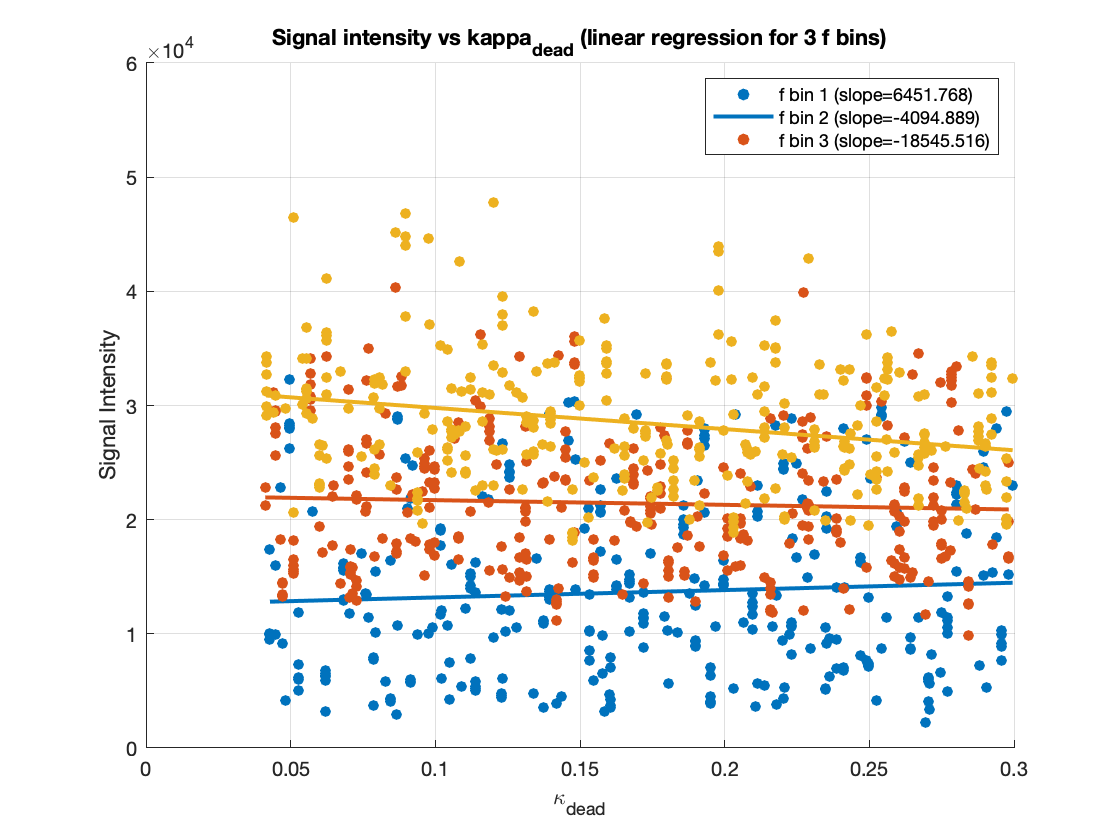

% Paramètres
b_index = 7;
td_index = 3;
num_bins = 3;  % nombre de bins pour f

% Extraction
f_all = params(:,1);
kappa_dead_all = params(:,6);
rsd_all = params(:,4);

% Filtre
valid_idx = rsd_all < 10; 
max_points = 1024;
valid_idx = find(valid_idx);          
if length(valid_idx) > max_points
    valid_idx = valid_idx(1:max_points);
end
kappa_dead = kappa_dead_all(valid_idx);
f = f_all(valid_idx);
sig_temp = squeeze(signals_4D(valid_idx, td_index, b_index, :));
sig_avg  = mean(sig_temp, 2);

% Définir les bins de f
edges = linspace(min(f), max(f), num_bins+1);

figure;
hold on;

colors = lines(num_bins); % couleur différente par bin
legend_entries = strings(num_bins,1); 

for i = 1:num_bins
    % Indices des points dans le bin i
    bin_idx = f >= edges(i) & f < edges(i+1);
    kappa_bin = kappa_dead(bin_idx);
    sig_bin   = sig_avg(bin_idx);

    % Tracer scatter
    scatter(kappa_bin, sig_bin, 30, 'filled', 'MarkerFaceColor', colors(i,:));

    % --- Régression linéaire ---
    if ~isempty(kappa_bin)
        coeffs = polyfit(kappa_bin, sig_bin, 1);  % 1 = linéaire
        slope = coeffs(1);                        % coefficient directeur
        k_fit = linspace(min(kappa_bin), max(kappa_bin), 100);
        sig_fit = polyval(coeffs, k_fit);
        plot(k_fit, sig_fit, '-', 'Color', colors(i,:), 'LineWidth', 2);
        legend_entries(i) = sprintf('f bin %d (slope=%.3f)', i, slope);
    end
end

xlabel('\kappa_{dead}');
ylabel('Signal Intensity');
title('Signal intensity vs kappa_{dead} (linear regression for 3 f bins)');
grid on;
legend(legend_entries);

## Plot signal vs kappa_dead colored by f_alive 

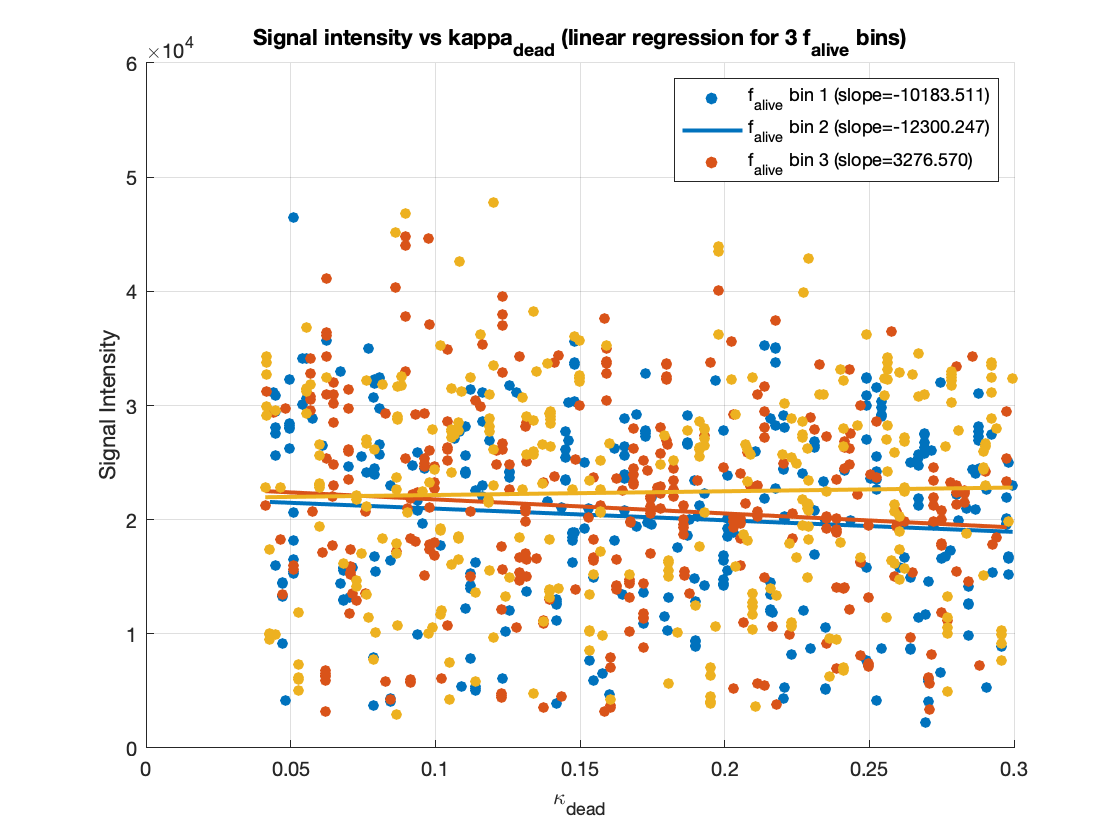

% Paramètres
b_index = 7;
td_index = 3;
num_bins = 3;  % nombre de bins pour f_alive

% Extraction
f_alive_all = params(:,7);
kappa_dead_all = params(:,6);
rsd_all = params(:,4);

% Filtre
valid_idx = rsd_all < 10; 
max_points = 1024;
valid_idx = find(valid_idx);          
if length(valid_idx) > max_points
    valid_idx = valid_idx(1:max_points);
end
kappa_dead = kappa_dead_all(valid_idx);
f_alive = f_alive_all(valid_idx);
sig_temp = squeeze(signals_4D(valid_idx, td_index, b_index, :));
sig_avg  = mean(sig_temp, 2);

% Définir les bins de f_alive
edges = linspace(min(f_alive), max(f_alive), num_bins+1);

figure;
hold on;

colors = lines(num_bins); % couleur différente par bin
legend_entries = strings(num_bins,1); 

for i = 1:num_bins
    % Indices des points dans le bin i
    bin_idx = f_alive >= edges(i) & f_alive < edges(i+1);
    kappa_bin = kappa_dead(bin_idx);
    sig_bin   = sig_avg(bin_idx);

    % Tracer scatter
    scatter(kappa_bin, sig_bin, 30, 'filled', 'MarkerFaceColor', colors(i,:));

    % --- Régression linéaire ---
    if ~isempty(kappa_bin)
        coeffs = polyfit(kappa_bin, sig_bin, 1);  % 1 = linéaire
        slope = coeffs(1);                        % coefficient directeur
        k_fit = linspace(min(kappa_bin), max(kappa_bin), 100);
        sig_fit = polyval(coeffs, k_fit);
        plot(k_fit, sig_fit, '-', 'Color', colors(i,:), 'LineWidth', 2);
        legend_entries(i) = sprintf('f_{alive} bin %d (slope=%.3f)', i, slope);
    end
end

xlabel('\kappa_{dead}');
ylabel('Signal Intensity');
title('Signal intensity vs kappa_{dead} (linear regression for 3 f_{alive} bins)');
grid on;
legend(legend_entries);

## Comparison both LUT

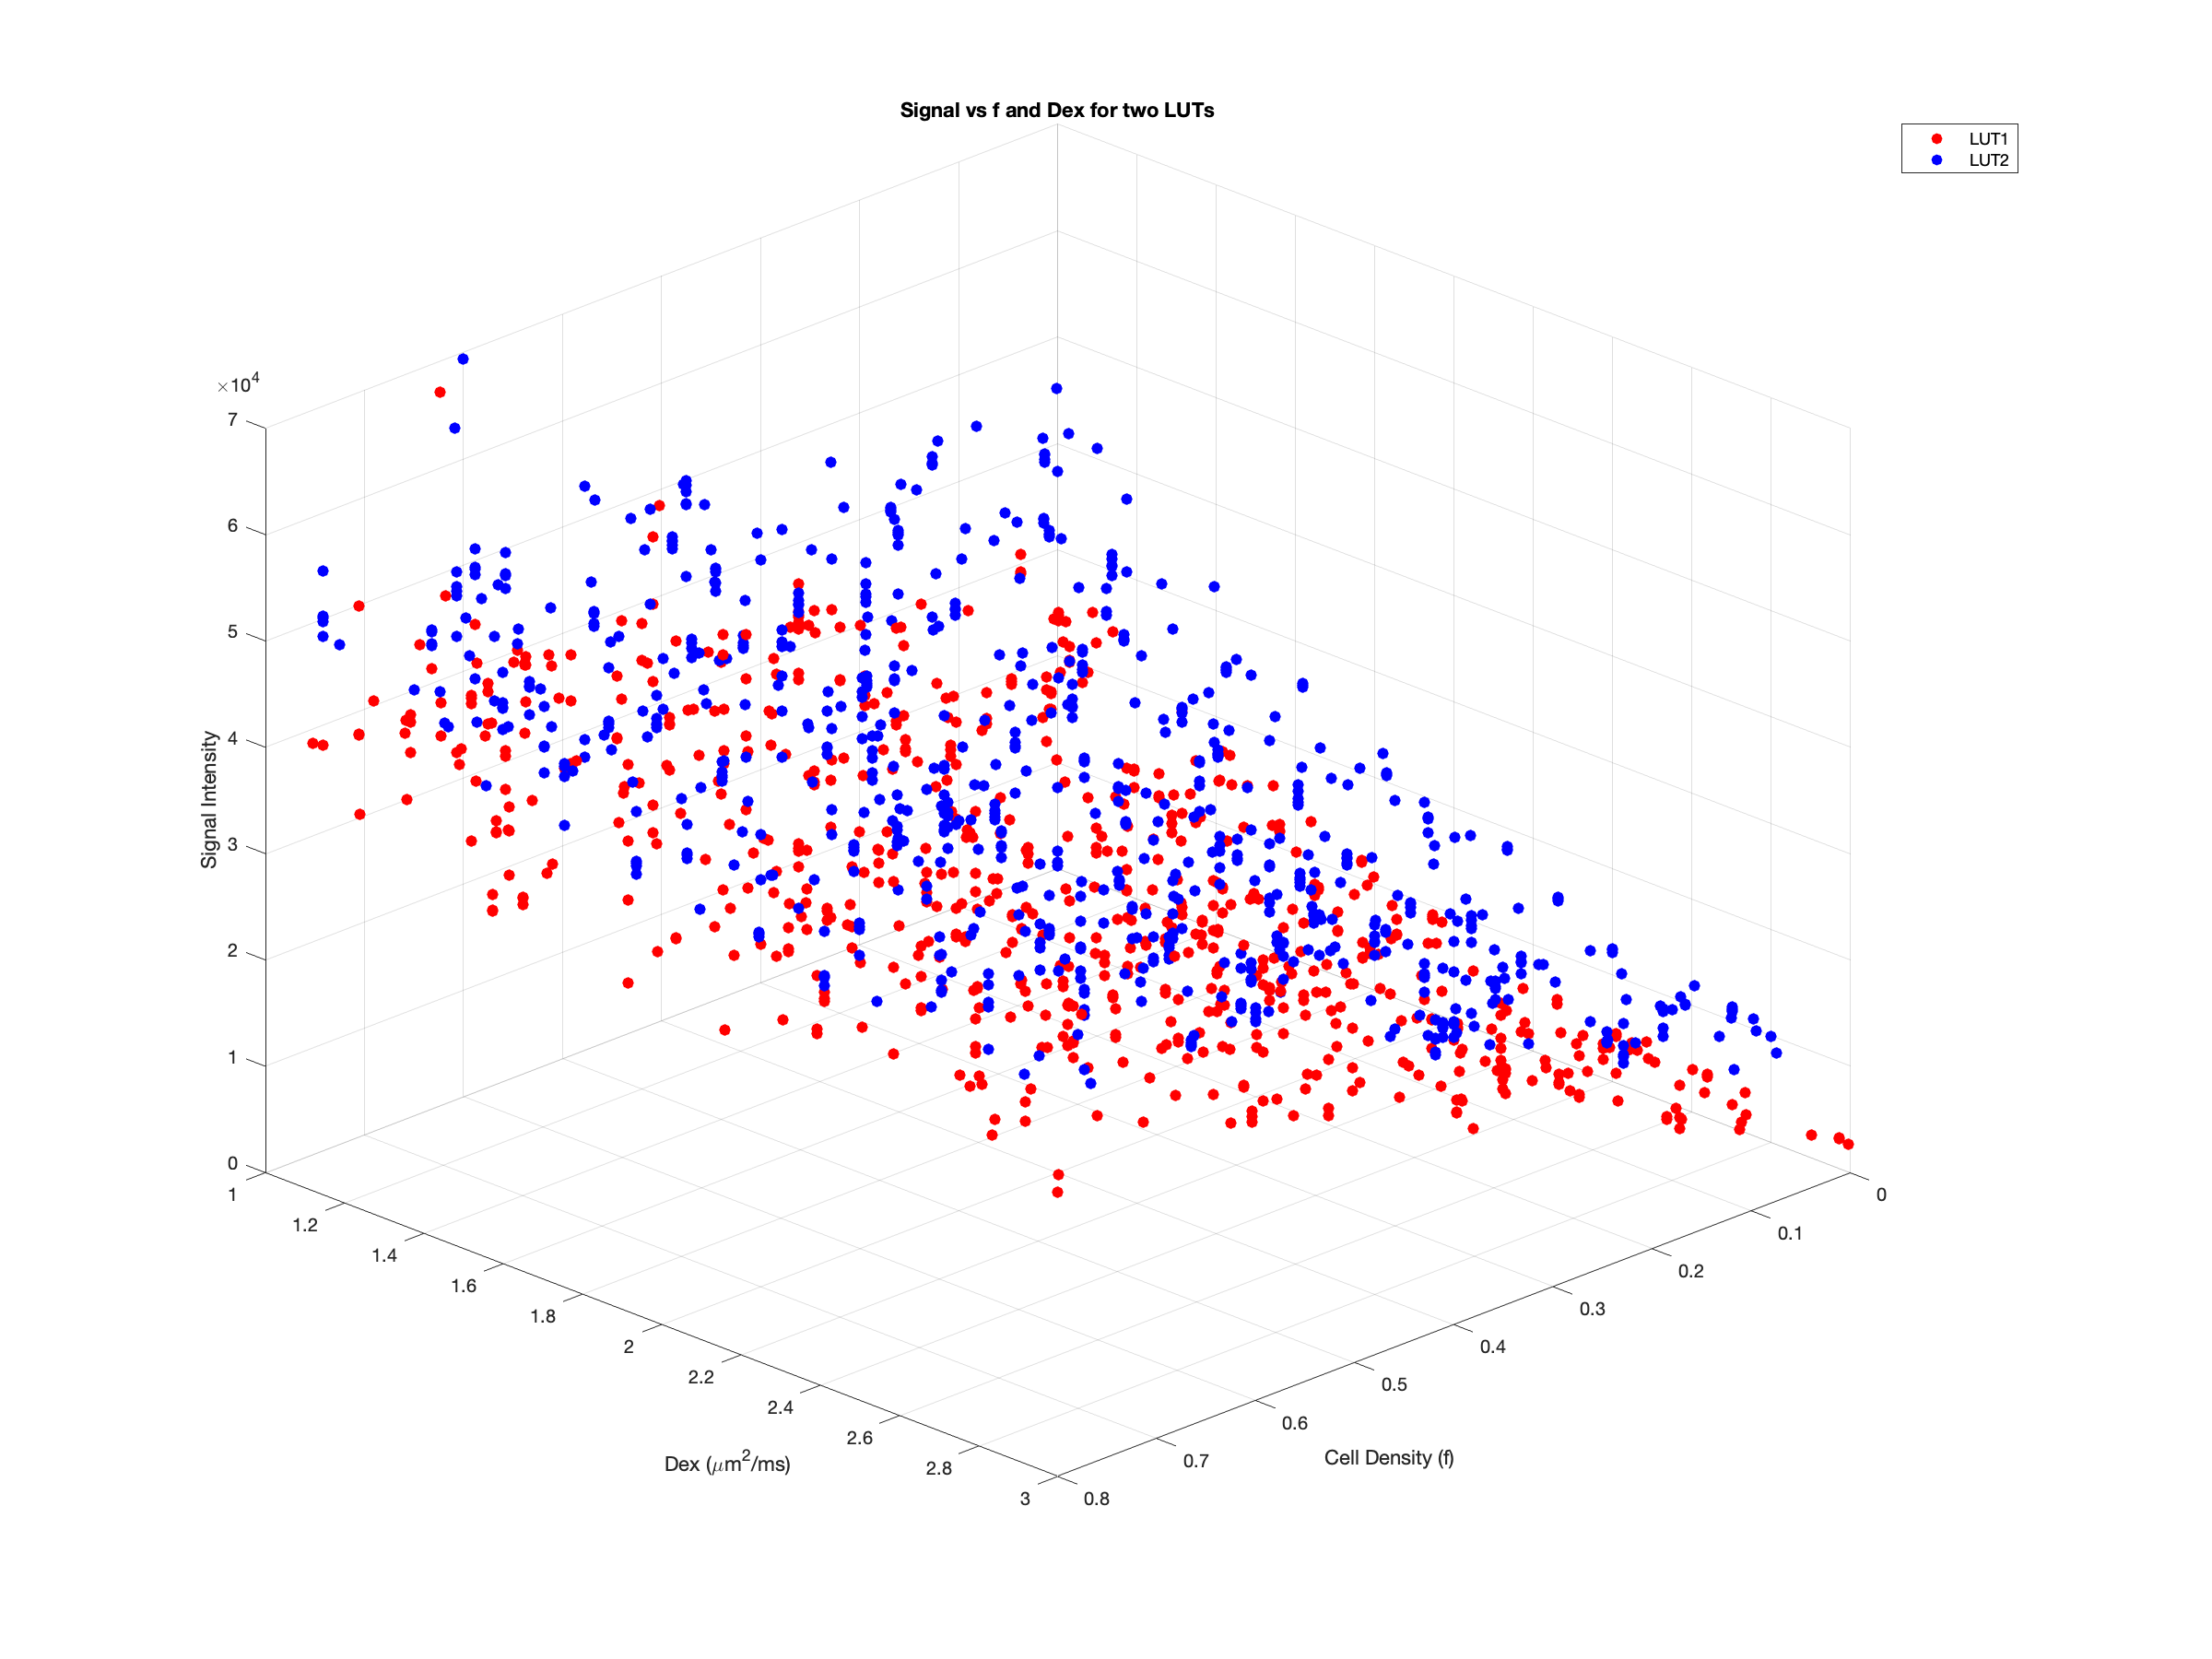

% --- Chargement des LUT ---
% Exemple si elles sont stockées en .mat
load('lookup_table.mat'); % contient params et signals
params_LUT1  = params;       % [N × nb_paramètres]
signals_LUT1 = signals_4D;   % [N × nTD × nB × nDirs]

load('lookup_table_two_pop.mat'); % contient params et signals
params_LUT2  = params;
signals_LUT2 = signals_4D;

%% --- Paramètres ---
% Supposons que tu as un vecteur bvals qui contient tous les b-values
b_target = 0.8;

% Trouver l'indice le plus proche
[~, b_index] = min(abs(bvals - b_target));
td_index = 3;
max_points = 1034;

colors = {'r','b'}; % LUT1 rouge, LUT2 bleu

figure('Position',[100 100 1200 900]);
hold on;

LUTs = {params_LUT1, signals_LUT1; params_LUT2, signals_LUT2};

for l = 1:2
    params_curr  = LUTs{l,1};
    signals_curr = LUTs{l,2};
    
    f_all   = params_curr(:,1); % f
    Dex_all = params_curr(:,2);
    rsd_all = params_curr(:,4);
    
    % Filtre f entre 1 et 3
    range_Dex = [1, 3];
    Dex_mask = Dex_all >= range_Dex(1) & Dex_all <= range_Dex(2);
    
    % Combiner avec le filtre existant
    valid_idx = find(rsd_all < 10 & Dex_mask);
    
    % Limiter à max_points
    if length(valid_idx) > max_points
        valid_idx = valid_idx(1:max_points);
    end

    
    f     = f_all(valid_idx);
    Dex   = Dex_all(valid_idx);
    sig_temp = squeeze(signals_curr(valid_idx, td_index, b_index, :));
    sig_avg  = mean(sig_temp, 2);
    
    % Scatter 3D
    scatter3(f, Dex, sig_avg, 40, colors{l}, 'filled');
end

xlabel('Cell Density (f)');
ylabel('Dex (\mum^2/ms)');
zlabel('Signal Intensity');
title('Signal vs f and Dex for two LUTs');
grid on;
view(135, 30);
legend('LUT1','LUT2');

## Plot evolution of signal average with the percentage of dead cells

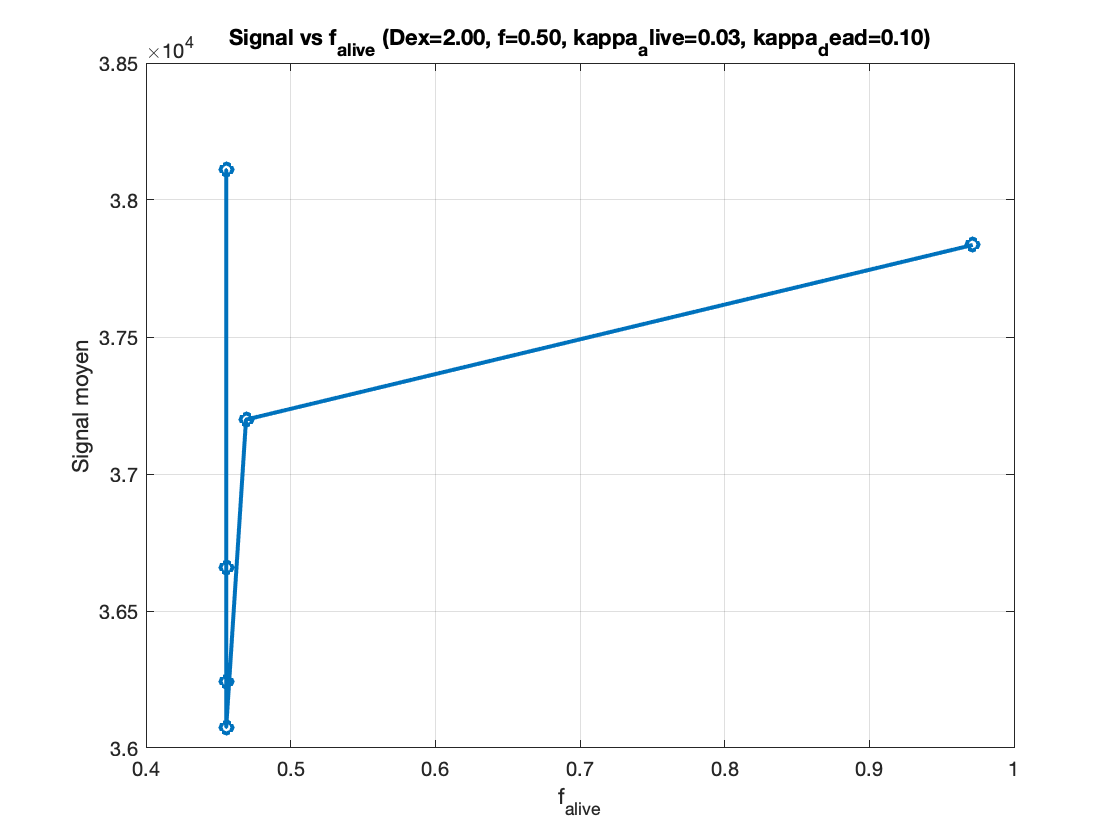

% --- Choix des paramètres fixes ---
Dex_target   = 2.0;     % µm^2/ms
f_target     = 0.5;     % fraction totale
kappa_dead_target = 0.1;     % perméabilité
kappa_alive_target = 0.03;   

td_index = 3;           % index du TD choisi
b_index  = 5;           % index du b-value choisi (par ex)

% --- Tolérances spécifiques ---
tol_Dex        = 0.05;
tol_f          = 0.05;
tol_kappa_alive = 0.001;
tol_kappa_dead  = 0.05;

% --- Filtrage avec tolérances spécifiques ---
mask = abs(params(:,2) - Dex_target)        < tol_Dex & ...
       abs(params(:,1) - f_target)          < tol_f & ...
       abs(params(:,5) - kappa_alive_target)< tol_kappa_alive & ...
       abs(params(:,6) - kappa_dead_target) < tol_kappa_dead;


idx = find(mask);

if isempty(idx)
    error('Aucun point LUT ne correspond aux paramètres fixes choisis.');
end

% --- Récupération des f_alive et signaux ---
f_alive = params(idx,7);  % colonne f_alive
sig_temp = squeeze(signals_4D(idx, td_index, b_index, :)); % [N × nDirs]
sig_avg  = mean(sig_temp, 2);

% --- Tri par f_alive ---
[f_alive_sorted, order] = sort(f_alive);
sig_sorted = sig_avg(order);

% --- Plot ---
figure;
plot(f_alive_sorted, sig_sorted, '-o','LineWidth',2);
xlabel('f_{alive}');
ylabel('Signal moyen');
title(sprintf('Signal vs f_{alive} (Dex=%.2f, f=%.2f, kappa_alive=%.2f, kappa_dead=%.2f)', ...
    Dex_target, f_target, kappa_alive_target, kappa_dead_target));
grid on;


% --- Récupération des paramètres pour les points trouvés ---
params_found = params(idx, :);   % tous les paramètres de la LUT correspondants
f_alive      = params_found(:,7);

% --- Calcul du signal moyen ---
sig_temp = squeeze(signals_4D(idx, td_index, b_index, :)); % [N × nDirs]
sig_avg  = mean(sig_temp, 2);

% --- Création d'un tableau ---
T = table(...
    params_found(:,1), ... % f total
    params_found(:,2), ... % Dex
    params_found(:,3), ... % rmean
    params_found(:,4), ... % rsd
    params_found(:,5), ... % kappa_alive
    params_found(:,6), ... % kappa_dead
    params_found(:,7), ... % f_alive
    sig_avg, ...           % signal moyen
    'VariableNames', {'f','Dex','rmean','rsd','kappa_alive','kappa_dead','f_alive','SignalAvg'});

disp(T);

       f        Dex      rmean      rsd      kappa_alive    kappa_dead    f_alive    SignalAvg
    _______    ______    ______    ______    ___________    __________    _______    _________

    0.51374    1.9973    39.584    9.2868       0.03         0.099598     0.45546      36241  
    0.51374    1.9973    15.692    9.2868       0.03         0.099598     0.45546      38110  
    0.51374    1.9973    39.584     3.337       0.03         0.099598     0.45546      36657  
    0.51374    1.9973    39.584    9.2868       0.03           0.1256     0.45546      36076  
    0.51374    1.9973    39.584    9.2868       0.03         0.099598     0.97148      37836  
    0.51288    2.0264    22.725    9.2125       0.03          